**Exercise 1. Write a function that calculates the correlation between two input vectors. Use only MATLAB functions (mean, std, etc.)**

vector1 = randn(1000,1);
vector2 = randn(1000,1);
correlation = corr(vector1, vector2);
correlation

correlation = -0.0373

**Exercise 2. Conduct Monte Carlo simulations in which samples are drawn from a Gaussian distribution with mean 10 and standard deviation 2. For each of various sample sizes (n = 2, 5, 10, 20, 50,100,200,500, 1000), draw 1,000 random samples, compute the mean of each sample, and quantify the spread in the results of computing standard deviation. Then make a line plot that shows the relationship between sample size (x-axis) and the uncertainty (spread) of the mean (y-axis). On the same figure, draw a line that shows the theoretical expectation.**

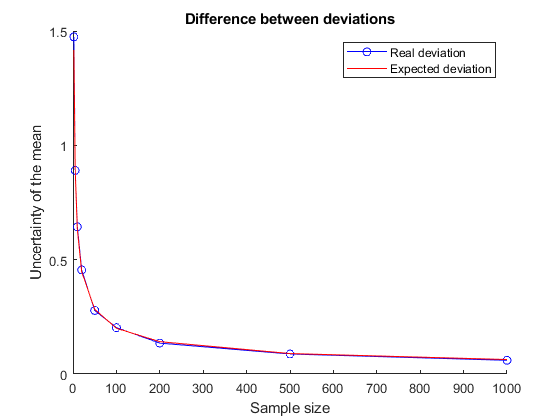

inputstddev = 2;
inputmean = 10;
samplesize = 1000;

results = zeros(1,1000);
sample_sizes = [2,5,10,20,50,100,200,500,1000];
devs = [];
expected_devs = [];

for i=1:length(sample_sizes)
        means = zeros(1,1000);
        for j=1:1000
            vector1 = inputmean + randn(sample_sizes(i),1)*inputstddev;
            means(j) = mean(vector1);
        end
        stDeviation = std(means);
        devs(end+1) = stDeviation;
        expected_devs(end+1) = 2 / sqrt(sample_sizes(i));
end

figure; hold on;
plot(sample_sizes, devs, 'b-o');
plot(sample_sizes, expected_devs, 'r-');
title('Difference between deviations');
xlabel('Sample size');
ylabel('Uncertainty of the mean');
hold off;

legend('Real deviation','Expected deviation')

**Exercise 3. Write a function that accepts an input vector and retums a new vector representing a bootstrap sample drawn from the original vector. **

inputvector = randn(10,1)

inputvector =     0.3596
   -0.8699
   -0.2579
    0.5332
    0.4721
    0.7836
    0.7959
    0.6266
    1.5147
    0.5593


bootstrapped = bootstrap(inputvector)

bootstrapped =     0.5332
    0.3596
    0.7959
    0.3596
    0.7959
    0.5593
    0.6266
    0.4721
    1.5147
    0.7959


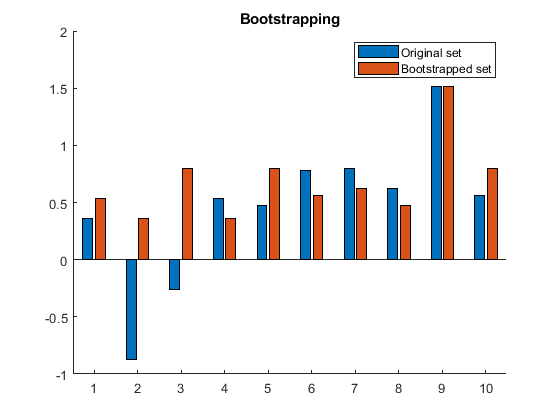


figure; hold on;
title('Bootstrapping')
bar([inputvector, bootstrapped]);
legend('Original set', 'Bootstrapped set')
hold off;

**Exercise 4. Modify the function in Exercise 3 to accept another input specifying the number of bootstrap samples to draw. Then have the function retum a 2D matrix with different bootstrap samples in the columns of the matrix. Avoid the use of for-loops in this function so that the function is fast. **

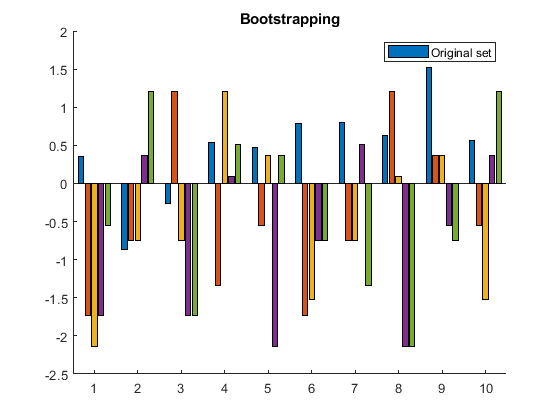

%Set the booststraps number
bootnumber = 4;
bootstrapped = bootstrap4(randn(10,1), bootnumber);
figure; hold on;
title('Bootstrapping')
bar([inputvector, bootstrapped]);
legend('Original set')
hold off;

disp('Bootstrapped sets:')

Bootstrapped sets:


bootstrapped

bootstrapped =    -1.7390   -2.1415   -1.7390   -0.5538
   -0.7451   -0.7451    0.3631    1.2071
    1.2071   -0.7451   -1.7390   -1.7390
   -1.3404    1.2071    0.0881    0.5158
   -0.5538    0.3631   -2.1415    0.3631
   -1.7390   -1.5259   -0.7451   -0.7451
   -0.7451   -0.7451    0.5158   -1.3404
    1.2071    0.0881   -2.1415   -2.1415
    0.3631    0.3631   -0.5538   -0.7451
   -0.5538   -1.5259    0.3631    1.2071


**Exercise 5. Generate some correlated data (two variables). Visualize the data using a scatter plot. Then compute a 2D histogram of these data and visualize the histogram as an image. Compute the marginal distribution of the data (showing the distribution of the data on each variable separately) and then compute the joint distribution that we would expect to observe if the variables were independent. Visualize this distribution as an image.**

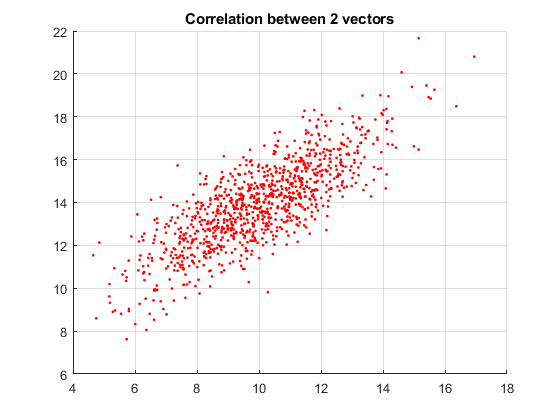

%Generate two correlating vectors%
input_mean = 10;
sigma = 2;
M = input_mean + sigma*randn(1000,2);
R = [1 0.8; 0.8 1];
L = chol(R);
M = M*L;
vector1 = M(:,1);
vector2 = M(:,2);

%Visualizing the data with use of scatter plot%
figure; hold on;
title('Correlation between 2 vectors');

scatter(vector1, vector2, 'r.');
grid;
hold off;

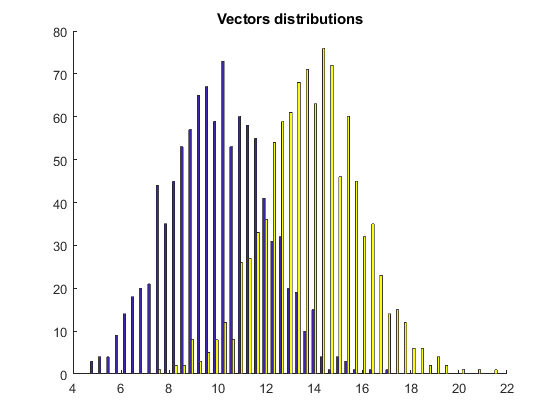


%Visualize both variables on the same bar chart%
figure; hold on;
title('Vectors distributions')
hist([vector1, vector2], 50);
hold off;

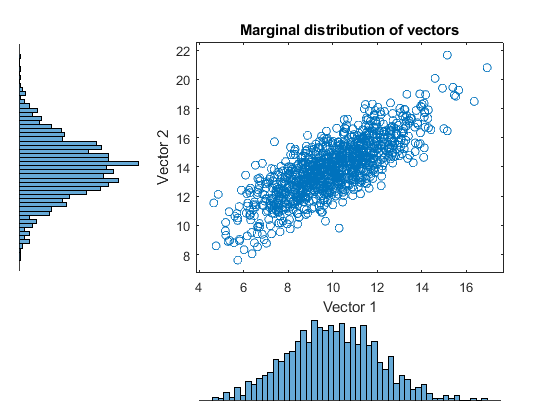


figure; hold on;
scatterhist(vector1, vector2, 50);
xlabel('Vector 1')
ylabel('Vector 2')
title('Marginal distribution of vectors')
hold off;

#### Function for Exercise 3

function s = bootstrap(x)
    indices = ceil(length(x) * rand(length(x),1));
    s = x(indices);
end


#### Function for Exercise 4

function s = bootstrap4(x, samples_number)
    indices = ceil(length(x) * rand(length(x),samples_number));
    s = x(indices);
end